# Razionale.

**Obiettivo della tesina**:

- Infarinatura di come è possible descrivere un sistema matematico/fisico.

- Simulazione.

- Controllo

- ecc.

# 1) Cruise Control.

### Cos'è il Cruise Control.

Il **Cruise Control** è un sistema elettronico che consente ad un veicolo di mantenere una velocità costante impostata dal conducente, senza la necessità di agire costantemente sull'acceleratore.

Principio di Funzionamento:

- **Impostazione della Velocità: **Il conducente imposta la velocità da mantenere, tramite pulsante o leva, e il sistema la memorizza come valore di riferimento.

- **Controllo della Velocità: **l'unità di controllo elettronico (**ECU**) monitora costantemente la velocità del veicolo tramite sensori (es, sensore di velocità). L'**ECU** confronta la velocità misurata con quella impostata: se è minore, l'ECU va ad agire sull'accelerazione per aumentarne la velocità, in caso contrario, si diminuisce l'accelerazione o si agisce sui freni.

- **Attuazione:** nel caso di motori a combustione, l'**ECU** agisce sull'acceleratore controllando elettronicamente l'iniezione del carburante e/o i freni, mentre per i veicoli elettrici si va ad agire direttamente sulla coppia (corrente) del motore. Per quest'ultimi, la gestione della decelerazione può essere gestita più facilmente sfruttando la frenata rigenerativa.

- **Disattivazione: **Il cruise control si disattiva automaticamente quando si preme il pedale del freno o anche tramite pulsante dedicato.

# 2) Analisi del modello Fisico.

### Descrizione del modello Fisico

Il **Cruise Control** è un sistema a retroazione con lo scopo di controllare la velocità di crociera e mantenere costante la velocità del veicolo nonostante i disturbi esterni, come le variazioni del vento o della pendenza della strada. Ciò avviene misurando la velocità del veicolo, confrontandola conquella di riferimento e regolando automaticamente l'acceleratore in base a una legge di controllo.

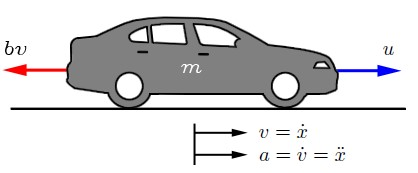

Si considera un semplice modello della dinamica del veicolo, mostrato nel diagramma a corpo libero (immagine sopra). Sul veicolo, di massa **m**, agisce una forza di controllo **u, **che rappresenta la forza generata all'interfaccia strada/pneumatico. In questo caso si assume di poterla controllare direttamente trascurando l'attrito dei pneumatici, della pendenza della strada ecc. che contribuiscono a generare le forze resistive. Per questo modello si considera l'attrito viscoso $\textrm{bv}$ (resistenza dell'aria) ipotizzando che vari linearmente con la velocità del veicolo $v$ e che agisca in direzione opposta al moto. La forma linearizzata dell'attrito viscoso vale per basse velocità fintanto che il moto dell'aria risulta essere laminare.

### **Equazione del modello Fisico **[Cruise Control: System Modeling](https://ctms.engin.umich.edu/CTMS/index.php?example=CruiseControl&section=SystemModeling).

Un modo per descrivere i **Sistemi Complessi** è quello di analizzarli nel dominio del tempo e le grandezze che variano (nel tempo) possono essere definite dalle relazioni in termini di **Equazioni Differenziali**. La soluzione a queste equazioni fornisce il **legame ingresso-uscita** che dipende dal segnale in ingresso e dalle condizioni al contorno. Si ha quindi, per questo Sistema, che sommando le forze nella direzione **x** e applicando la seconda legge di Newton, si ottiene la seguente equazione:

#### 
$$\sum m\dot{v} =u-\textrm{bv}\to m\dot{v} +\textrm{bv}=u$$


che rapprsenta un'**Equazione Differenziale del primo ordine**, Lineare Tempo Invariante** (LTI)** --> **Descrivere meglio equazioni LTI. **Dal momento che si è interessati a controllare la **velocità** del veicolo, l'equazione di uscita può essere scritta come:

#### 
$$y=v$$


### **Descrizione del modello fisico con Equazioni di Spazio di Stato **[System Modeling](https://ctms.engin.umich.edu/CTMS/index.php?example=Introduction&section=SystemModeling).

Data la precedente** Equazione Differenziale **e generalizzata in questa forma: 

#### 
$$\sum_{i\;=\;0}^n {\;a}_i \;\;\frac{{\mathrm{d}}^i }{\mathrm{d}t^i }y\left(t\right)=u\left(t\right)$$


può essere descritta da un modello **Spazio di Stato**, che è una rappresentazione matematica di un sistema fisico come un insieme di variabili di input, di output e di stato correlate da **Equazioni Differenziali del Primo Ordine**. Le variabili di stato definiscono i valori delle variabili di output. Di seguito il modello nella forma standard:

#### 
$$\left\lbrace \begin{array}{ll}
\dot{\mathit{\mathbf{x}}} =\textrm{Ax}+\textrm{Bu} & \\
y=\textrm{Cx}+\textrm{Du} & 
\end{array}\right.$$


Dove:

- $x$ : vettore di stato delle variabili (nx1). 

- $\dot{x} \;$: derivata (rispetto il tempo) del vettore di stato (nx1).

- $u\;$: input o vettore di cotrollo (px1).

- $y$: vettore di output (qx1).

- $A$: matrice di sistema (nxn).

- $B$: matrice di input (nxp).

- $C$: matrice di output (qxn).

- $D$: matrice di feedforward (qxp)

In particolare la matrice di uscita $C\;$viene utilizzata per specificare quali variabili di stato (o combinazioni di esse) sono disponibili per l'utilizzo da parte del controllore. Dal momento che si è interessati a controllare la velocità del Sistema, si esplicita l'**Equazione Differenziale** in funzione di $v$:

#### 
$$\left\lbrace \begin{array}{ll}
\dot{v} =-\frac{\mathrm{b}}{m}v+\frac{u}{m} & \\
y=x & 
\end{array}\right.$$


In questo caso il sistema **Cruise Control**, descritto da una sola **Equazione Differenziale**, lo si rappresenta tramite **Equazioni di Spazio di Stato**:

#### 
$$\left\lbrack \dot{v} \right\rbrack =\left\lbrack \frac{-b}{m}\right\rbrack \left\lbrack v\right\rbrack +\left\lbrack \frac{1}{m}\right\rbrack \left\lbrack u\right\rbrack$$


Il Tool di simulazione **Matlab**, permette di utilizzare la funzione `ss` per  convertire modelli di sistemi dinamici nella forma di modello stato-spazio che risulta essere utile per Rappresentare un modello** Lineare Tempo Invariante (LTI)** ed eseguire la progettazione di controllo, che è lo scopo di questo elaborato.

% Preparazione script.
clc
clear
close all

% Dati del sistema.
m = 1000; % Massa del veicolo [kg].
b = 50;   % Coefficiente di attrito viscoso [Ns/m].
u = 500;  % Forza applicata al sistema [N].

% Matrici stato-spazio.
A = -b/m;
B = 1/m;
C = 1;
D = 0;

% Rappresentazione del sistema in forma di Spazio di Stato.
ss_cruise = ss(A,B,C,D)


ss_cruise =
 
  A = 
          x1
   x1  -0.05
 
  B = 
          u1
   x1  0.001
 
  C = 
       x1
   y1   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties


### **Descrizione del modello fisico con Trasformata di Laplace.**

Per risolvere le **Equazioni Differenziali Lineari **risulta conveniente descrivere il problema di origine attraverso una trasformazione reversibile. Uno strumento che, dato un segnale di ingresso qualsiasi, fornisca calcoli semplici è dato dalla trasformazione dei sistemi dal dominio nel **tempo** a dominio **s**. Questo strumento è dato dalla **Trasformata di Laplace** dove la risoluzione di **Equazioni Differenziali **viene semplificata portando alla soluzioni di **Equazioni Lineari Algebriche**. La **Funzione di Trasferimento** di un sistema lineare è definito come il rapporto della trasformata di **Laplace** della variabile di uscita $Y\left(s\right)$ rispetto quella della variabile in ingresso $U\left(s\right)$, con tutte le condizioni iniziali poste a zero. La **FdT** di un generico sistema fisico è dato da:

#### 
$$F\left(s\right)=\frac{Y\left(s\right)}{U\left(s\right)}$$


che risulta essere un rapporto tra polinomi a coefficienti costanti e reali in **s**, dove il grado del polinomio al denominatore deve essere maggiore o uguale al grado del polinomio al numeratore. 

### **Rappresentazione del modello fisico con Schemi a Blocchi.**

In presenza di **SIstemi Complessi** risulta essere molto utile rappresentare la **Funzione di Trasferimento** tramite **Schemi a Blocchi**, dove l'azione causa-effetto è rappresentato da un blocco rettangolare e da un segmento entrate (ingresso) da uno uscente (uscita). Il **Cruise Control** è un sistema la cui FdT può essere descritto da il seguente schema: 

dove si ha:

- $P\left(s\right)$: funzione di trasferimento.

- $U\left(s\right)$: ingresso.

- $V\left(s\right)$: uscita.

 L' **Equazione Differenziale **che descrive il **Cruise Control** può essere riscritta in forma di Laplace come segue:

#### 
$$m\dot{v} +\textrm{bv}=u\to \textrm{msV}\left(s\right)\;+\textrm{bV}\left(s\right)=U\left(s\right)$$


si esplicita l'equazione rispetto la variabile di uscita e si porta la variabile di ingresso al denominatore. La **Fdt** del processo risulta essere:

#### 
$$V\left(s\right)\left(b+\textrm{ms}\right)=U\left(s\right)\to P\left(s\right)=\frac{V\left(s\right)}{U\left(s\right)}=\frac{1}{b+\textrm{ms}}\;\left\lbrack \frac{m/s}{N}\right\rbrack$$


e può essere riscritta in forma canonica:

#### 
$$P\left(s\right)=\frac{1}{b+\textrm{ms}}=\frac{K}{1+\tau s}\;\;\;\;\textrm{con}\;\left\lbrace \begin{array}{ll}
K=\frac{1}{b} & \\
\tau =\frac{m}{b} & 
\end{array}\right.$$


**Matlab** mette a disposizione diversi strumenti per convertire modelli di **Sistemi Dinamici** in forma di funzioni di trasferimento:

- **ss2tf**: converte la rappresentazione dello spazio di stato in funzione di trasferimento.

- **tf**: rappresenta il modello della funzione di trasferimento.

% Conversione del sistema in funzione di trasferimento
[num,den] = ss2tf(A,B,C,D);

tf_cruise_ = tf(num,den)


tf_cruise_ =
 
   0.001
  --------
  s + 0.05
 
Continuous-time transfer function.
Model Properties


Rappresentazione in Forma Canonica.

% Forma canonica.
K = 1/b;
Tau_p = m/b;

s = tf('s'); % Creazione variabile 's'.
P = K/(1 + Tau_p*s) % FdT del processo 'P' (Cruise Control).


P =
 
    0.02
  --------
  20 s + 1
 
Continuous-time transfer function.
Model Properties


% P = 1/(b + m*s)

# 3) Analisi del sistema.

### **Sistema a Catena Aperta.**

Stabilità del sistema: [Cruise Control: Root Locus Controller Design](https://ctms.engin.umich.edu/CTMS/index.php?example=CruiseControl&section=ControlRootLocus).

La stabilita del sistema è determinata dalla posizione dei poli della funzione di trasferimento nel piano complesso s. Un **Sistema Lineare Tempo-Invariante (LTI)** è stabile se e solo se tutti i **poli** della sua funzione di trasferimento hanno parte reale negativa e quindi si trovano nel semipiano sinistro del **piano s**. Per verificare questo si pongono i poli uguale della **FdT **a 0:

#### 
$$P\left(s\right)=\frac{1}{b+\textrm{ms}}\to b+\textrm{ms}=0\to s=-\frac{b}{m}\;\;\;\;\textrm{con}\;b,m>0\;\;$$


Il **Sistema** risulta avere un solo polo con parte reale negativa, quindi stabile. Per verificare queste condizioni, **Matlab** mette a disposizione diverse funzioni, alcune di queste sono:

- **pole**: restituisce i poli del sistema.

- **pzmap**: restituisce poli e zeri del sistema e li plotta.

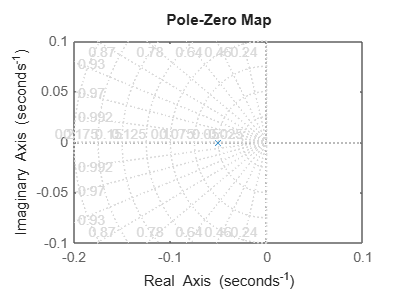

% Poli del Sistema 'P'.
P_poli = pole(P);

% Mappa dei poli del Sistema 'P'.
pzmap(P);
axis([-0.2 0.1 -0.1 0.1])
grid on

Specifiche di prestazione: [Cruise Control: System Analysis](https://ctms.engin.umich.edu/CTMS/index.php?example=CruiseControl&section=SystemAnalysis).

Dal momento che il **Sistema** è stabile, si definiscono le specifiche da soddisfare:

- $\textrm{Ts}$: Tempo di salita < 10 [s].

- $\textrm{Os}$: Overshoot < 10 [%].

- $e$: Errore a regime < 2 [%].

Si impone al sistema una forza **u** di 500 [N] per far raggiungere al veicolo una velocità **v** di 10 [m/s] (circa 36 [km/h]) dove si suppone il moto dell'aria ancora laminare (condizione per far valere la linearizzazione dell'attrito viscoso). Per verificarne le prestazioni, si stimola il Sistema con un segnale a gradino 

/*********/

dare dettaglio del segnale a gradino 

/*********/

Per ottenere questo, **Matlab** mette a disposizione le seguenti funzioni: 

- **step**: risposta a gradino di un sistema dinamico.

- **RespConfig**: opzioni per la risposta a gradino.

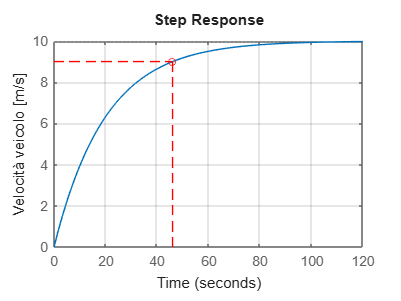

% Plot risposta a gradino.
respCfg = RespConfig('Amplitude',u);
[y,t] = step(P,respCfg);
stepplot(P,respCfg)

% Plot puntino rosso.
hold on
x_plot = t(51);
y_plot = y(51);
plot(x_plot,y_plot,'o','MarkerSize',5,'Color','r');
hold on

% Plot linee tratteggiate.
plot([0, x_plot], [y_plot, y_plot],'--','Color','r'); % Tratteggio orizzonale.
hold on
plot([x_plot, x_plot], [0, y_plot],'--','Color','r'); % Tratteggio verticale.
hold off;

% Legenda.
grid on;
ylabel('Velocità veicolo [m/s]');

Dalla figura della **risposta a gradino** si nota che il **Sistema **non ha **Overshoot** (risultato aspettato in quanto sistema del primo ordine) e la risposta a regime raggiunge la valocità desiderata di 10 [m/s], ma il **Tempo di Salita** (90% del tempo totale di salita) lo raggiunge dopo circa 46 [s]. Dal momento che quest'ultima specifica non è rispettata, risulta necessario progettare un controllore a **Catena Chiusa** che permetta di raggiungere le prestazioni desiderate, mantenedo la stabilità del sistema.

/***********/

Errore a regime (Teorema del valore finale) ????????????????

/***********/

### **Sistema a Catena Chiusa.**

- Modello del Sistema.

- Stabilità del sistema.

- Specifiche di prestazione: [Cruise Control: Root Locus Controller Design](https://ctms.engin.umich.edu/CTMS/index.php?example=CruiseControl&section=ControlRootLocus).

- Specifiche di prestazione: [Prestazioni a regime.](https://ctms.engin.umich.edu/CTMS/index.php?example=Introduction&section=SystemAnalysis#8)

- Sintesi del controllore dal punto di vista teorico (vedere foglio con calcoli fatti a mano).

- Sintesi del controllore con [Matlab PID Tuner](https://it.mathworks.com/help/control/ref/pidtuner-app.html).

- Stabilità del sistema (Bode + Luogo Radici).

- Errore a regime (Teorema del valore finale).

- Video Control Tutorials: [ Control Specifications and PID Control](https://www.youtube.com/watch?v=RYWPqb2hAEM).

- Lezioni dispense 40/42 - 50/56.

- Specificare errore nullo a regime per sistemi del primo ordine (dispense 38 e 47).

# 4) Conclusioni.

Teorema del valore finale:

non `e possibile applicare questo teorema ”bendati”, cio`e calcolare il valore finale senza prima controllare se il sistema `e stabile. Se il sistema `e stabile il teorema `e applicabile e il limite restituisce un valore sensato. 

Se ci troviamo nel secondo e nel terzo quadrante del piano cartesiano significa cheabbiamo poli con parte reale Re < 0: questo significa che il sistema `e stabile ed eventualmente tender`a a zero.